# Feedforward neural network

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

buffer = 1.0e+05 *

    4.2228    4.2262    4.2266    4.2207    4.2202    4.2298    4.2226    4.2259    4.2212    4.2286    4.2203    4.2277    4.2237    4.2189    4.2221    4.2286    4.2240    4.2251    4.2282    4.2322    4.2230    4.2277    4.2216    4.2242    4.2238    4.2260    4.2297    4.2270    4.2250    4.2290    4.2218    4.2251    4.2318    4.2226    4.2242    4.2237    4.2286    4.2265    4.2243    4.2284    4.2200    4.2255    4.2265    4.2257    4.2279    4.2240    4.2252    4.2215    4.2197    4.2254
    0.0101    0.0120   -0.0149   -0.0120    0.0077    0.0040    0.0045    0.0109    0.0032    0.0066    0.0117    0.0113    0.0076   -0.0098   -0.0041   -0.0107   -0.0010    0.0070   -0.0109    0.0012    0.0113    0.0082   -0.0099    0.0027   -0.0055   -0.0177    0.0083   -0.0154   -0.0093    0.0121   -0.0030    0.0044   -0.0155   -0.0021   -0.0067    0.0030    0.0075    0.0053    0.0055   -0.0070   -0.0084   -0.0019    0.0117    0.0003    0.0053    0.0038   -0.0030    0.000

Nbuffer_variables = 28

Nsamples = 11000

Ninputs = 22

Noutputs = 5

ans =           22       11000


ans =            5       11000


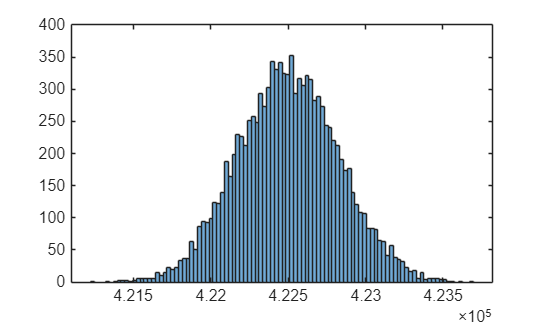

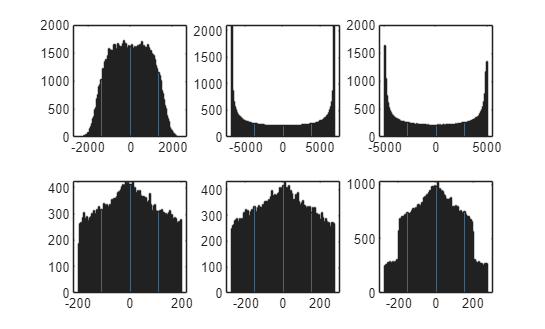

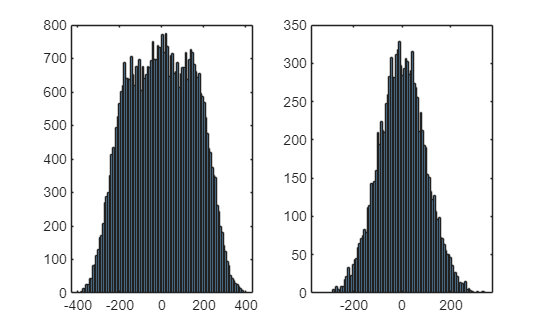

ans = 159.6243

ie_max = 393.8507

ix_max = 200

iy_max = 280

is_max = 250

vo_max = 1000

vB_max = 12000

C = 0.0050

vc_mean_ref = 13000

Xmax = 1.0e+05 *

    4.6475
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0770
    0.0770
    0.0770
    0.0550
    0.0550


Ymax =          500
         500
         500
         500
        1000


Ninputs = 22

Nsamples = 11000

Noutputs = 5

Nsamples = 11000

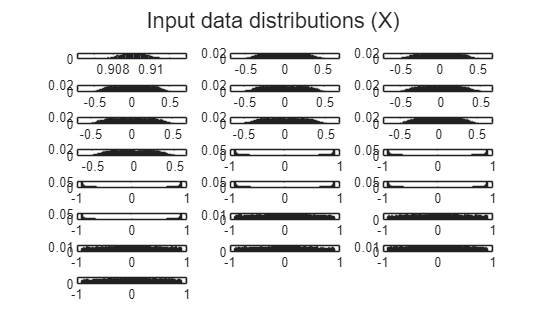

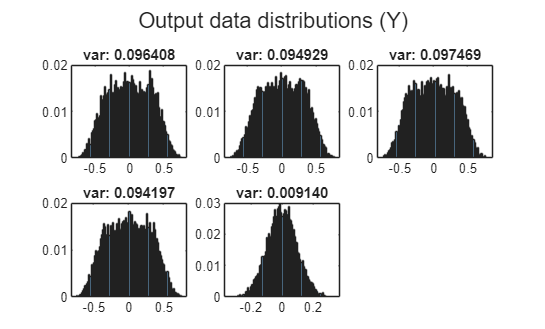

run('DataPreparation.mlx');

save_net = true; % Overwrite current feedforward architecture

## Architecture

argsFFNN                  = struct();
argsFFNN.Ninputs          = Ninputs;
argsFFNN.Noutputs         = Noutputs;
argsFFNN.Nlayers          = 1;
argsFFNN.Nneurons         = 3*Ninputs;
argsFFNN.HiddenActivation = 'relu';
argsFFNN.OutputActivation = 'tanh';
argsFFNN.Dropout          = 0;
argsFFNN.WinitFcn         = 'glorot';
argsFFNN.BinitFcn         = 'glorot';
argsFFNN.BatchNorm        = true;
argsFFNN.TrainBias        = true;

FFnet = FFNNgenerator(argsFFNN)

FFnet =   dlnetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
    Connections: [10×2 table]
     Learnables: [10×3 table]
          State: [4×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1

  View summary with summary.


## Training

output_variance = var(extractdata(dlY_tr), 0, 2);
var_e = mean(output_variance(1:4));
var_o = output_variance(5);
ErrorWeights = [ones(4, 1); var_e/var_o]

ErrorWeights =     1.0000
    1.0000
    1.0000
    1.0000
   10.4564



argsFFNNtrain                     = struct();
argsFFNNtrain.net                 = FFnet;
argsFFNNtrain.X_tr                = dlX_tr;
argsFFNNtrain.Y_tr                = dlY_tr;
argsFFNNtrain.X_val               = dlX_val;
argsFFNNtrain.Y_val               = dlY_val;
argsFFNNtrain.InitialLearningRate = 1e-2;
argsFFNNtrain.FinalLearningRate   = 1e-6;
argsFFNNtrain.Plots               = 'training-progress'

argsFFNNtrain = struct with fields:
                    net: [1×1 dlnetwork]
                   X_tr: [22×10000 dlarray]
                   Y_tr: [5×10000 dlarray]
                  X_val: [22×1000 dlarray]
                  Y_val: [5×1000 dlarray]
    InitialLearningRate: 0.0100
      FinalLearningRate: 1.0000e-06
                  Plots: 'training-progress'


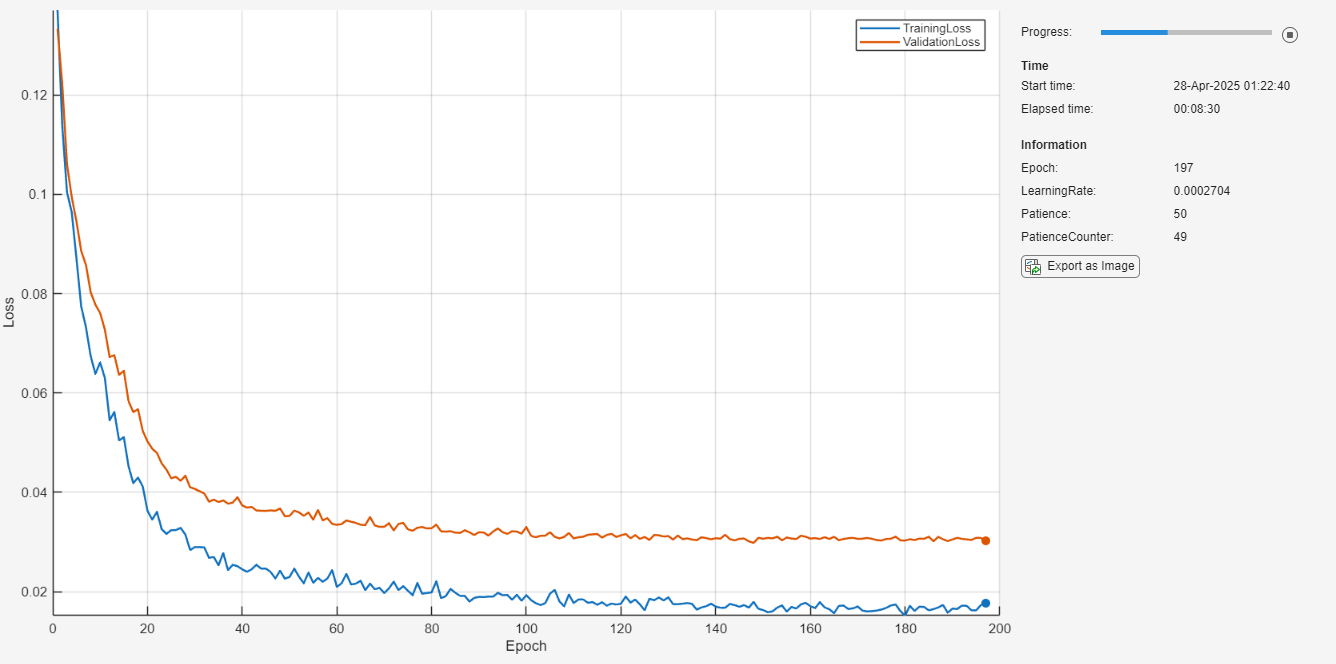

Early stopping at epoch 198: no improvement after 50 epochs.


FFnet =   dlnetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
    Connections: [10×2 table]
     Learnables: [10×3 table]
          State: [4×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1

  View summary with summary.


argsFFNNtrain.Verbose             = false;
argsFFNNtrain.MaxEpochs           = 500;
argsFFNNtrain.MiniBatchSize       = 128; % This could be adaptive during training for better fitting and generalization
argsFFNNtrain.ValidationPatience  = 50;
argsFFNNtrain.HuberThreshold      = 1;
argsFFNNtrain.ErrorWeights        = ErrorWeights;

FFnet = FFNNtrain(argsFFNNtrain, 'custom')


if save_net
    save('ImitationLearning\ActualArchitecture\FFnet.mat', "FFnet")
end

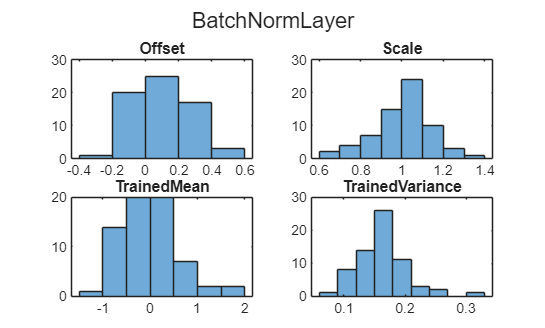

figure
subplot(2, 2, 1)
histogram(FFnet.Layers(3).Offset)
title('Offset')
subplot(2, 2, 2)
histogram(FFnet.Layers(3).Scale)
title('Scale')
subplot(2, 2, 3)
histogram(FFnet.Layers(3).TrainedMean)
title('TrainedMean')
subplot(2, 2, 4)
histogram(FFnet.Layers(3).TrainedVariance)
title('TrainedVariance')
sgtitle('BatchNormLayer')

## Summary

trainPerformance = dlfeval(@FFNNLoss, FFnet, dlX_tr, dlY_tr, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);
valPerformance   = dlfeval(@FFNNLoss, FFnet, dlX_val, dlY_val, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 0.017086


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 0.029815


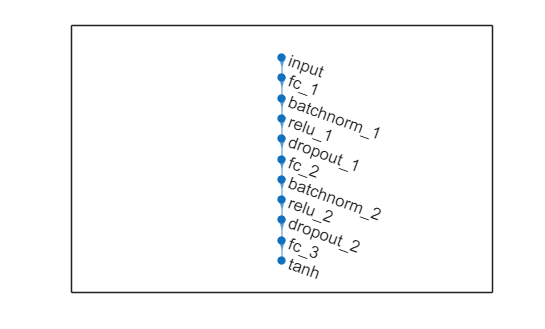


figure
plot(FFnet)

analyzeNetwork(FFnet);
summary(FFnet)


   Initialized: true

   Number of learnables: 6.5k

   Inputs:
      1   'input'   22 features



# Performance analysis

## Complete timeseries

% pred = extractdata(FFnet.predict(dlX));
% figure
% subplot(ceil(Noutputs/3), 3, 1)
% stairs(1:Nsamples, Y(1, :))
% hold on
% stairs(1:Nsamples, pred(1, :))
% hold off
% for idx = 2:Noutputs
%     subplot(ceil(Noutputs/3), 3, idx)
%     stairs(1:Nsamples, Y(idx, :))
%     hold on
%     stairs(1:Nsamples, pred(idx, :))
%     hold off
% end
% sgtitle('Complete timeseries');

## Error histogram

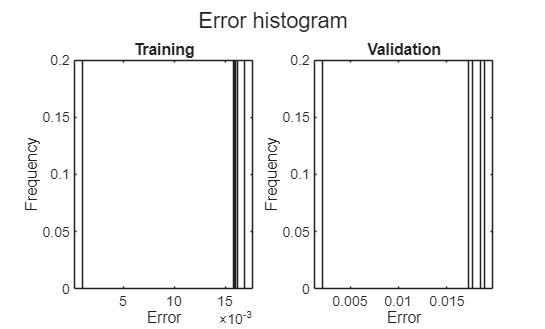

Y_tr_pred = extractdata(FFnet.predict(dlX_tr));
Y_val_pred = extractdata(FFnet.predict(dlX_val));

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 1000, 'Normalization', 'probability')
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 1000, 'Normalization', 'probability')
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

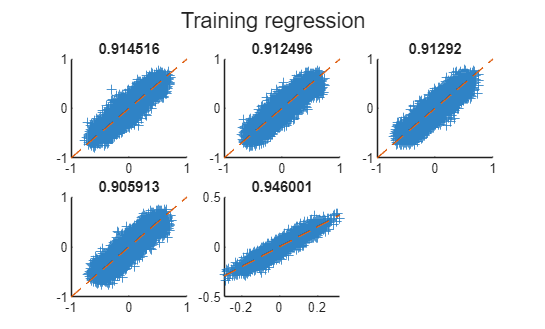

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

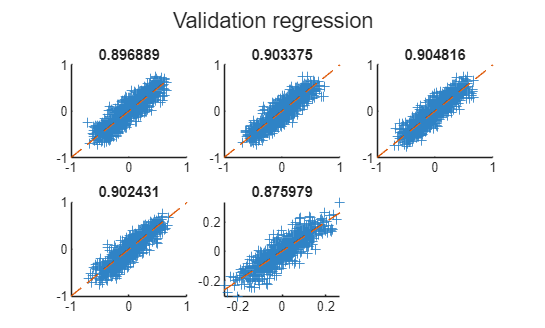


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

Learnables = FFnet.Learnables

Learnables = 10×3 table
        Layer        Parameter         Value     
    _____________    _________    _______________

    "fc_1"           "Weights"    {66×22 dlarray}
    "fc_1"           "Bias"       {66×1  dlarray}
    "batchnorm_1"    "Offset"     {66×1  dlarray}
    "batchnorm_1"    "Scale"      {66×1  dlarray}
    "fc_2"           "Weights"    {66×66 dlarray}
    "fc_2"           "Bias"       {66×1  dlarray}
    "batchnorm_2"    "Offset"     {66×1  dlarray}
    "batchnorm_2"    "Scale"      {66×1  dlarray}
    "fc_3"           "Weights"    { 5×66 dlarray}
    "fc_3"           "Bias"       { 5×1  dlarray}


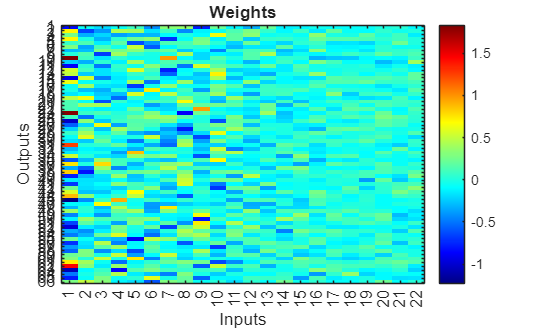

Learnables = Learnables.Value;

weights_input_hidden = extractdata(Learnables{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(abs(weights_input_hidden(:)))

weights_treshold = 0.0183

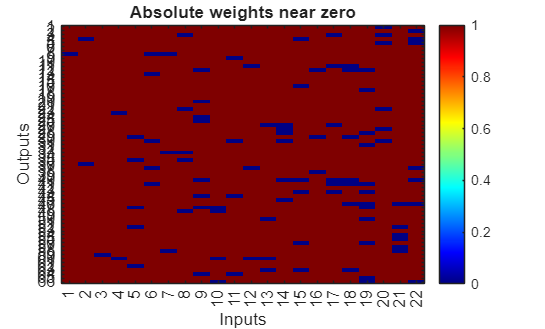

weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));